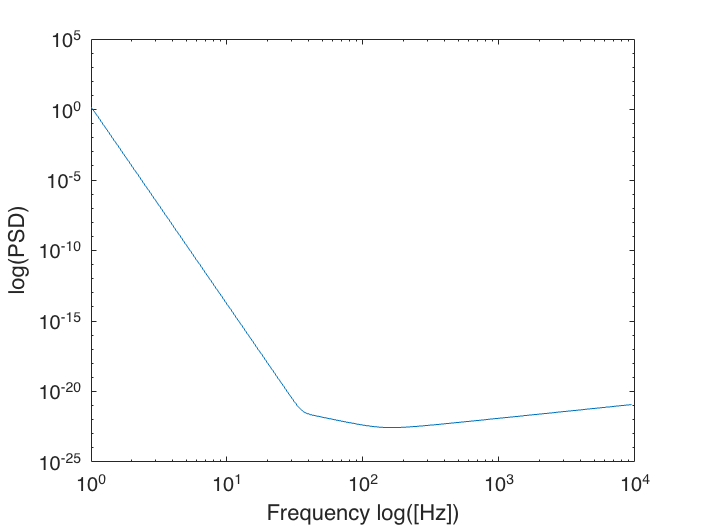

%Lab 8 part 2
%Luis Mario Bres Castro

iLigofile=load('iLIGOSensitivity.txt', '-ascii');
freq=iLigofile(:,1)';
sqrtPSD=iLigofile(:,2)';

loglog(freq,sqrtPSD)
xlabel('Frequency log([Hz])')
ylabel('log(PSD)')

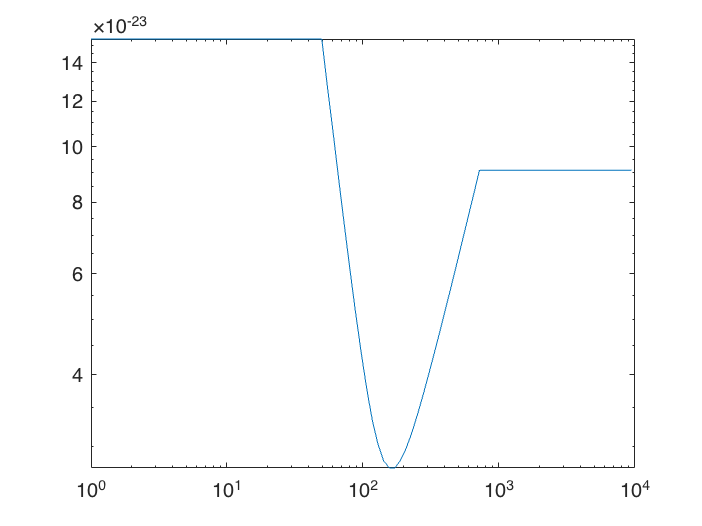

%Modifications
sampFreq = 6000; %Hz

% fsi=find(freq>=sampFreq/2)
% PSD_fsi=sqrtPSD(86);
f50=freq(42);
f50_ind=42;
Psd50=sqrtPSD(42);
f700=find(freq>=700);
freq(70);
f700_ind=70;
Psd700=sqrtPSD(70);


iLigofile(1,2)=sqrtPSD(42);
iLigofile(1:42,2)=Psd50;
iLigofile(70:end,2)=Psd700;



iLigofile(2:end+1,:) = iLigofile;
iLigofile(1,1)=0;
iLigofile(1,2)=Psd50;

f=iLigofile(:,1)';
PSD=iLigofile(:,2)';
loglog(f,PSD)

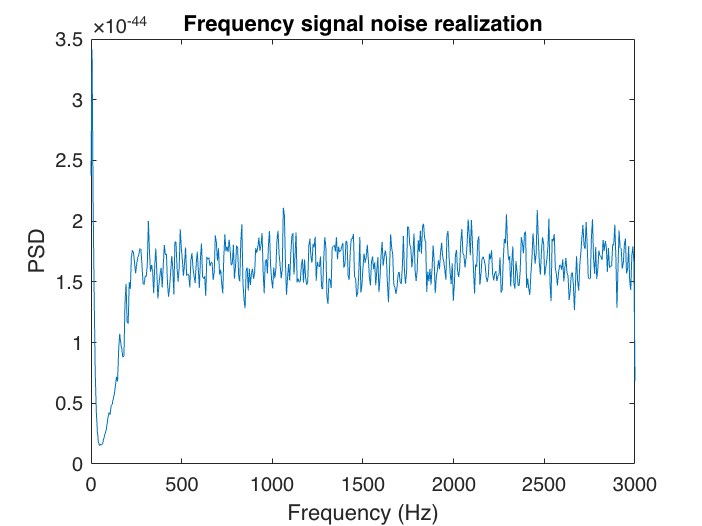

%Number of samples to generate
nSamples =10*sampFreq;
filtrOrd=600;

b = fir2(filtrOrd,f/f(end),PSD);
inNoise = randn(1,nSamples);
LigoNoise = sqrt(sampFreq)*fftfilt(b,inNoise);

[pxx,fl]=pwelch(LigoNoise, 1000,[],[],sampFreq);
figure;
plot(fl,pxx);
xlabel('Frequency (Hz)');
title('Frequency signal noise realization')
ylabel('PSD');

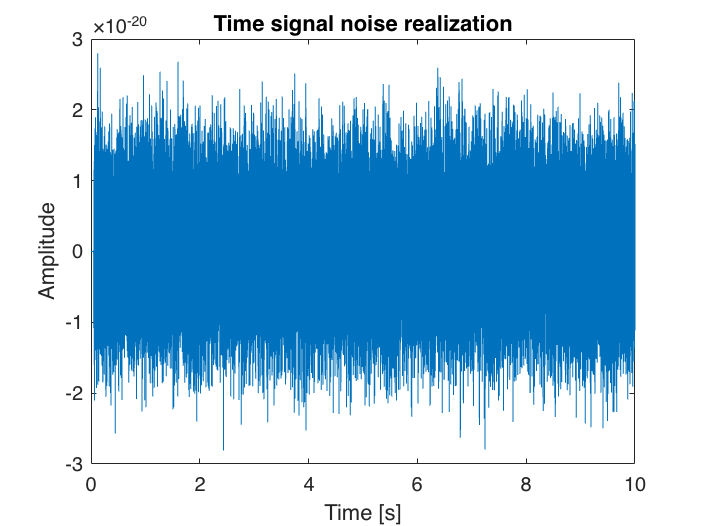

% Plot the colored noise realization
figure;
timeVec=(0:nSamples-1)/sampFreq;
plot(timeVec,LigoNoise);
xlabel('Time [s]')
ylabel('Amplitude')
title('Time signal noise realization')